This lesson is based off of the following notes:[https://www.astro.princeton.edu/~gk/A403/polytrop.pdf](https://www.astro.princeton.edu/~gk/A403/polytrop.pdf)

The purpose of this document is to study polytropes. They serve as crude models of stars. They are self-gravitating gaseous shperes. They cannot simulate the behaviour of a star but will serve to illustrate how a large sphere gravitates. We will be observing plots of the different polytropic indices and the steps along the way. The goal of these MATLAB-simulink assisted tutorials is the ability to visualise how things change with graphs. Polytropes in particular have the property that only some parts can be sovled analytically, we will therefore chime in with plotted numerical solutions to visualise. We begin by assuming that they are in hydrostatic equilibrium, from which we can describe using two first order differential equations. Please have the notes that this is based off of handy. Not every important bit of information is listed here. 


$$\frac{dP}{dr}=\frac{GM_{r}}{r^{2}}\rho$$
        

and


$$\frac{dM_{r}}{dr}=4\pi r^{2}\rho$$


The former is describing the change in pressure as a function of mass contained in the radius, the radius and the density of the object. The latter describes how much mass if contained in the given radius. To visualize these quantities,  let's go ahead and plot them. We will plot a series of diffrent density values to observe its effect.

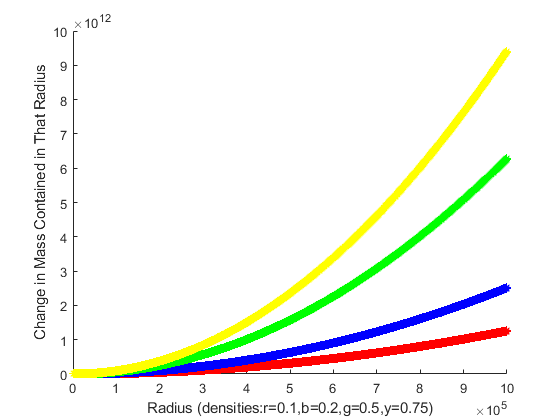

%we must begin with the differential equation for mass as a function of
%radius. There will be pauses in here to see graphs, proceed past them with
%a keystroke.
close all
clear all
%this will fill our structure array with the data that we need
counter=1;
for density=[0.1 0.2 0.5 0.75]
    for i=1:1000:1000000
        mass(counter).dMr_dr(i,1)=i;
        mass(counter).dMr_dr(i,2)=4*(3.14159)*(i.^2)*density;
    end
    counter=counter+1;
end

hold on 
plot(mass(1).dMr_dr(:,1),mass(1).dMr_dr(:,2),'r*')
plot(mass(2).dMr_dr(:,1),mass(2).dMr_dr(:,2),'b*')
plot(mass(3).dMr_dr(:,1),mass(3).dMr_dr(:,2),'g*')
plot(mass(4).dMr_dr(:,1),mass(4).dMr_dr(:,2),'y*')
xlabel('Radius (densities:r=0.1,b=0.2,g=0.5,y=0.75)')
ylabel('Change in Mass Contained in That Radius')
hold off 
pause(2)

close gcf

Clearly we see a simple r^2 relationship that is scaled by the density. We can now go ahead and perform some algebra, differentiate the first differential equation with respect to r and subsitute in the second to obtain a second order poisson equation.


$$\frac{1}{r^{2}}\frac{d}{dr}(\frac{r^{2}}{\rho}\frac{dP}{dr})=-4\pi G \rho$$


We now assume a polytropic relation between pressure and density


$$P=K\rho^{1+\frac{1}{n}}$$


K and n are real and positive constants, n is the plolytropic index. We introduce some dimentionless variables.


$$\rho=\rho_{c}\theta^{n}$$
     
$$P=P_{c}\theta^{n+1}$$
   
$$r=\alpha\xi$$


Alpha is a constant which is constructed from a host of variables. See the paper this is based off of to observe these quantities and understand their meanings here. The purpose of this is to obtain our equation in dimensionless variables as follows:


$$\frac{1}{\xi^{2}}\frac{d}{d\xi}(\xi^{2}\frac{d\theta}{d\xi})=-\theta^{n}$$


With initial conditions $\theta = 1$ and $\frac{d\theta}{d\xi}=0$ at $\xi=0$.

It is important to note that $\theta
$ ranges from 1 at the core to 0 at the surface, that will be the boundary for our plots. 

Now that we have established a differential equation and its solutions, let's plot them. The case where n==0, we will have an incompressible fluid. 

%the case where n==0

%a function of the variable xi
for i=0:0.0001:10
    xi(counter,1)=i;
    xi(counter,2)=1-((i.^2)./6);
    if xi(counter,2)<0
        break
    end
    counter=counter+1;
end
hold on
plot(xi(:,1),xi(:,2),'r*')
xlabel('Xi(blue n==1, red n==0)')
ylabel('Theta ')
pause(2)

The corresponding (n==0) density is constant and the corresponding pressure is linear. This is a rough approximation to a rocky planet like Earth for example. Next we can observe the next analytic solution which is the n==1 case. We will plot this on top of the previous case in order to observe the differences. 

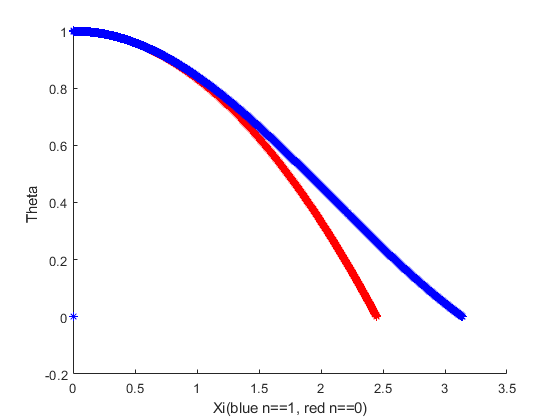

for i=0.001:0.0001:10
    xi_1(counter,1)=i;
    xi_1(counter,2)=sin(i)./i;
    if xi_1(counter,2)<0
        break
    end
    counter=counter+1;
end
plot(xi_1(:,1),xi_1(:,2),'b*')
hold off

pause(20)
close gcf

This is quite interesting as the behaviour of these two polytropes is very similar below Xi==1. For the Xi==1 case, the density scales linearly from the core density to the surface and the pressure scales as second order from the core to the surface of our polytrope.  